# Polynomial Zonotope Operations:

This Script Demonstrates Polynomial Zonotope and Several Operations

## Example of a Polynomial Zonotope:

Consider the following polynomial zonotope:

$$\mathcal{PZ} = \left\langle \begin{bmatrix} 2 & 3 & 0 & 1 \\ 0 & 2 & 4 & 2 \end{bmatrix}, \begin{bmatrix} 0 & 1 & 0 & 2 \\ 0 & 0 & 2 & 1 \end{bmatrix},[1,2] \right\rangle = \left\{ \begin{bmatrix} 2 \\ 0 \end{bmatrix} + \begin{bmatrix} 3 \\ 2 \end{bmatrix} \alpha_1 + \begin{bmatrix} 0 \\ 4 \end{bmatrix} \alpha_2^2 + \begin{bmatrix} 1 \\ 2 \end{bmatrix} \alpha_1^2 \alpha_2 \mid \alpha_1, \alpha_2 \in [-1,1] \right\}$$

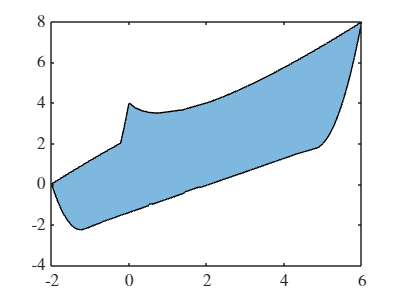

% Create a Polynomial Zonotope:
PZ = PolynomialZonotope([2 3 0 1;0 2 4 2],[0 1 0 2;0 0 2 1]);
plot(PZ);

## Example: Conversion from Ellipsoidal Set

Polynomial Zonotopes can Approximate other set representations, such as Ellipsoids

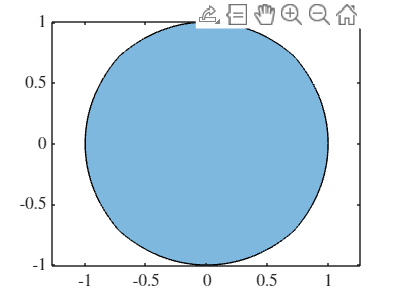

E = PolynomialZonotope(Ellipsoid([1 0;0 1],[0;0]));
plot(E); axis equal;

## Example: Minkowksi Sum of Polynomial Zonotopes

Minkowski Sums can be computed exactly from polynomial zonotopes:

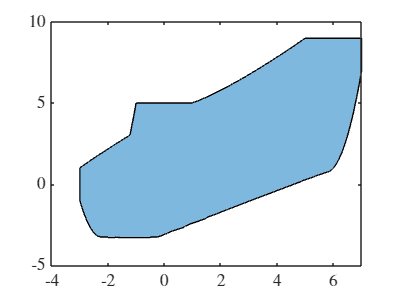

PZE = MinkowskiSum(PZ,PolynomialZonotope([1 0;0 1],[1 0;0 1]));
plot(PZE,struct('Splits',15));

## Example: Linear Map of a Polynomial Zonotope

Linear Maps can be computed as well:

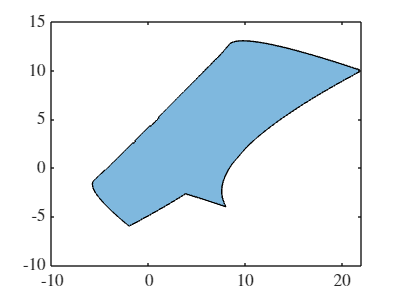

M = [1 2;3 -1];
PZM = LinearMap(PZ,M);
plot(PZM);

## Example: Tensor Map of a Polynomial Zonotope

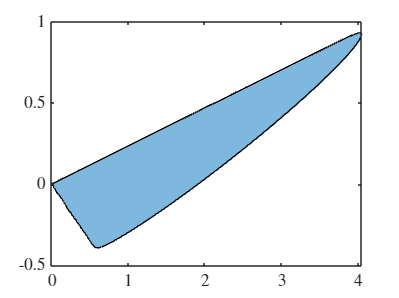

T = randn(2,2,2);
ET = TensorMap(E,T);
plot(ET,struct('Splits',15));

## Example: Order Reduction of a Polynomial Zonotope:

PZ = PolynomialZonotope(randn(2,20),randi([0,2],[2,20]));